# Recovery of Potassium Nitrate from an Anthraquinone Dye Alkali Wastewater by Crystallization

Group EHMT-12: Aswin Raghunathan (5128188) & Shyam Sundar Hemamalini (5071984)

## 1   Given Properties

The values of the given parameters are given.

w_feed_per = 35; % wt percentage
epsilon_prod = 0.95;
phi_feed = 40/3600; % m^3/s
tau = 16000; % s
rho_cr = 2100; % kg/m^3
rho_water = 1000; % kg/m^3
rho_sol = 1250; % kg/m^3
rho_vap = 3; % kg/m^3
mu_sol = 0.885e-3; % Pa s
H_cr = 0; % J/mol
H_evap = 1443*1000; % J/kg
Cp_liquid = 3.11*1000; % J/kg/°C
Cp_crystal = 0.32*1000; % J/kg/°C
m_h20 = 100; % g
U = 800; % W/m^2K

## 2   MSMPR Crystallization Model

### 2.1 Size Distribution of Crystals

The given size distribution of KNO3 crystals with respect to different crsytal lengths is plotted using the code given below.

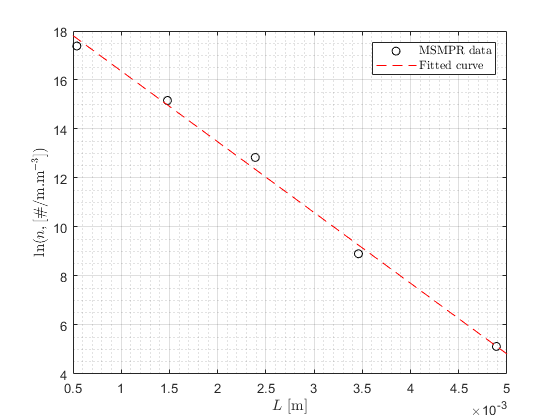

% Crystal Length (in m)
L = [4.89e-3  3.46e-3  2.39e-3  1.48e-3  0.54e-3];

% Population Density of Crystals 
n_L = [1.68e+02  7.39e+03  3.76e+05  3.85e+06  3.56e+07];
n_log = log(n_L);

% Population Density vs Crystal Length Plot
figure();
[X1, Y1] = prepareCurveData(L,log(n_L));
f1 = fit(X1, Y1, 'poly1');
plot(L,log(n_L),'ko');
hold on;
plot(f1,'r--');
xlabel('$L\ [\mathrm{m}]$','interpreter','latex');
ylabel('$\ln(n, [\mathrm{\#/m.m^{-3}}])$','interpreter','latex');
legend('MSMPR data','Fitted curve','interpreter','latex');
grid on; grid minor;

### 2.2. Factors affecting Crystallization Kinetics

The slope (p1) and y-intercept (p2) are detemined from the fitted curve from cftool.

p1 = -2888;
p2 = 19.25;

The parameters affecting the kinetics of crystallization are deterimed using the slope and intercept values found above.

G = -1/(p1*tau) % Growth Rate

G = 2.1641e-08

B = exp(p2)*G % Nucleation Rate

B = 4.9597

L_mean = 4*G*tau % Mean Crystal Length

L_mean = 0.0014

## 3   Design Decisions

### 3.1 Estimation of Solubility of KNO3 in Weight Percentage 

The solubility of KNO3 crystals in wt% is computed using the code given below.

% Temperature (in °C)
T = linspace(0,100,11);
T = sort([T 25]);

% Solubility (in g per 100g H2O)
Sol = [13.28  20.8  31.71  38.06  45.67  64.09  85.53...
    109.86  132.77  169.04  210.20  245.42];

% Solubility (in wt%)
Sol_wt = Sol./(Sol + 100)*100;

### 3.2 Solubility Curve of KNO3

The solubility of KNO3 crystals in wt% is plotted against varying temperature.

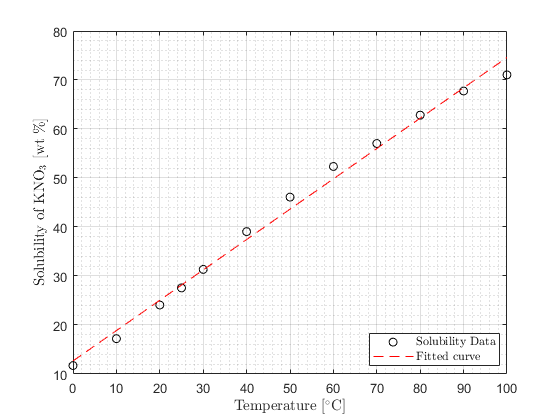

figure();
[X2, Y2] = prepareCurveData(T,Sol_wt);
f2 = fit(X2, Y2, 'poly1');
plot(T,Sol_wt,'ko');
hold on;
plot(f2,'r--');
xlim([0.0 100.0])
ylim([10.0 80.0])
xlabel('Temperature [$\mathrm{^{\circ} C}$]','interpreter','latex');
ylabel('Solubility of KNO$_3$ [$\mathrm{wt\ \%}$]','interpreter','latex');
legend('Solubility Data','Fitted curve','interpreter','latex','location','best');
grid on; grid minor;

### 3.3 Feed Temperature

The feed temperature is obtained by linear interpolation of the values from the solubility curve for a given equilibirum concentration.

w_feed = w_feed_per/100;
m_kno3 = -m_h20*w_feed/(w_feed - 1); % g
C_eq = m_kno3/(m_kno3 + m_h20) % g/g of solution

C_eq = 0.3500


T_feed = interp1(Sol_wt,T,C_eq*100) % °C

T_feed = 34.7343

### 3.4 Crystallization Method

The change in concentration with temperature is detemined to decide the crystallization method.

dC_dT = 0.006193 % g/g°C

dC_dT = 0.0062

From the obtained values above, *cooling crystallization method* is chosen.

## 4   Mass Balance

### 4.1 Estimation of Composition of the Product Stream

The amount of crystal equals solid fraction times the total mass of the feed.

phi_cr = (1-epsilon_prod)*rho_sol*phi_feed/rho_cr % m^3/s

phi_cr = 3.3069e-04

phi_cr_hr = phi_cr*3600 % m^3/hr

phi_cr_hr = 1.1905

The mass of KNO3 at inlet is equal to the liquid fraction times the total mass of the feed.

phi_pn_in = w_feed*phi_feed % m^3/s

phi_pn_in = 0.0039

phi_pn_in_hr = phi_pn_in*3600 % m^3/hr

phi_pn_in_hr = 14

From component balance of KNO3, we get,

phi_pn_out = phi_pn_in - rho_cr*phi_cr/rho_sol % m^3/s

phi_pn_out = 0.0033

phi_pn_out_hr = phi_pn_out*3600 % m^3/hr

phi_pn_out_hr = 12.0000

From the total mass balance, we get,

phi_sol_out = phi_feed - ((rho_cr*phi_cr)/rho_sol)

phi_sol_out = 0.0106

phi_sol_out_hr = phi_sol_out*3600 % m^3/hr

phi_sol_out_hr = 38

The ratio of mass of KNO3 to the total mass of the feed gives the weight fraction of KNO3.

w_prod = phi_pn_out/phi_sol_out

w_prod = 0.3158

### 4.2 Estimation of Operating Temperature

By linear interpolation of the solubility curve for the obtained composition of the stream, we can find the operating temperature.

T_operating = interp1(Sol_wt,T,w_prod*100) % °C

T_operating = 30.2949

The obtained operating temperature is lower than the feed temperature as expected for the considered cooling crystallization method.

### 4.3 Estimation of Product Flow Rate

The liquid fraction of feed is assumed to be 1. The product flow rate is determined from the mass balance as given below.

epsilon_feed = 1;
phi_prod = (phi_feed*rho_sol*epsilon_feed)/(rho_cr*(1-epsilon_prod) + epsilon_prod*rho_sol) % m^3/s

phi_prod = 0.0107

phi_prod_hr = phi_prod*3600 % m^3/hr

phi_prod_hr = 38.6847

### 4.4 Production Rate of Crystal

The mass flow rate of the crystal is determined from the crystall flow rate as follows.

m_cr = phi_cr*rho_cr; % kg/s
m_cr_day = m_cr*3600*24

m_cr_day = 6.0000e+04

The obtained production rate is greater than 50 tons/day. Hence, *continuous operation mode* is selected.

## 5   Energy Balance

The mass flow rates of feed and solution are computed as follows.

m_feed = phi_feed*rho_sol; % kg/s
m_sol = phi_sol_out*rho_sol; % kg/s

The total heat energy can be computed as given below.

Q = m_feed*Cp_liquid*(T_feed + 273.15) - (m_sol*Cp_liquid*(T_operating + 273.15)...
    + m_cr*Cp_crystal*(T_operating + 273.15)) % W

Q = 7.7968e+05

The initial temperature of coolant is assumed to be at ambient temperature.

T_in_water = 20; % °C

The specific heat capacity is assumed to be constant as temperature change is very small.

Cp_water = 4184.4; % J/kgK

The mass flow rate of coolant in the jacket is assumed as given below.

m_water = 20; % kg/s

The outlet temperature of the coolant can be computed from the energy balance as below.

T_out_water = T_in_water + (Q/(m_water*Cp_water)) % °C

T_out_water = 29.3165

The logarithmic mean temperature difference is calculated as shown below.

T_lmtd = ((T_feed - T_out_water) - (T_operating - T_in_water))/...
    (log((T_feed - T_out_water)/(T_operating - T_in_water)))

T_lmtd = 7.5972

### 5.1 Estimation of Total Area and Heat Capacity

The total area required for heat exchange is calculated below.

A = Q/(U*T_lmtd) %m^2

A = 128.2843

The total heat capacity is computed below.

Q_cr = Q/m_cr % J/kg crystal

Q_cr = 1.1227e+06

## 6   Volume of Crystallizer

The volume of the crystallizer can be determined from the product flow rate and the residence time provided as below.

V_cr = phi_prod*tau % m^3

V_cr = 171.9321